Calibration with same params from donut calibration

x = imu_d.MagFieldmagnetic_fieldy;
y = imu_d.MagFieldmagnetic_fieldx;
xcal = x - ellipse_t_ini.X0_in;
ycal = y - ellipse_t_ini.Y0_in;
m_trans = [xcal ycal];
theta = -atan2(0.03521416, 0.223612);
t_mat = [cos(theta) -sin(theta); sin(theta) cos(theta)];
m_rot = t_mat * m_trans';

Yaw from Magnetometer (before calibration)

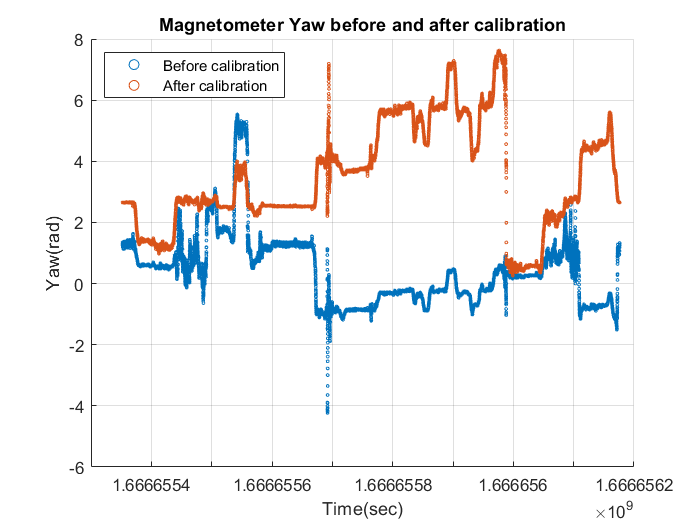

hold off

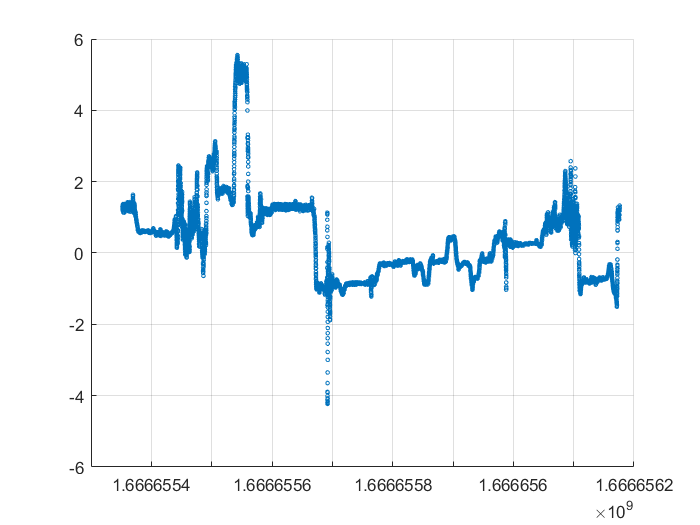

yaw_b = atan2(y, x);
yaw_b = unwrap(yaw_b);
time = imu_d.Time;
scatter(time, yaw_b, 5)
grid on

%% Equation from here
%%https://students.iitk.ac.in/roboclub/2017/12/21/Beginners-Guide-to-IMU.html#:~:text=As%20in%20accelerometer%20one%20can,calculate%20yaw%20using%20accelerometer%20itself%3F

Yaw from Magnetometer (after calibration)

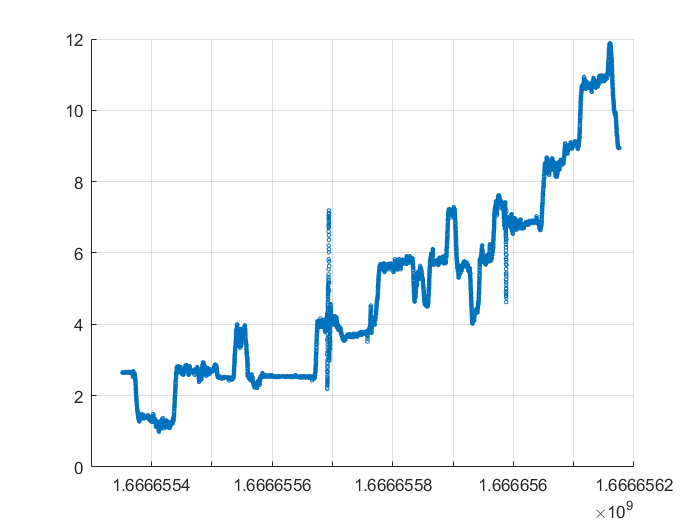

yaw_a = atan2(m_rot(2,:),m_rot(1,:));
yawg = yaw_a;
yawg(25000:25700) = movmean(yawg(25000:25700),20);
yaw_a = unwrap(yaw_a');
yawg = unwrap(yawg);
time = imu_d.Time;
yaw_a = yawg;
scatter(time, yaw_a, 5)
grid on

Comparison between the two

hold off

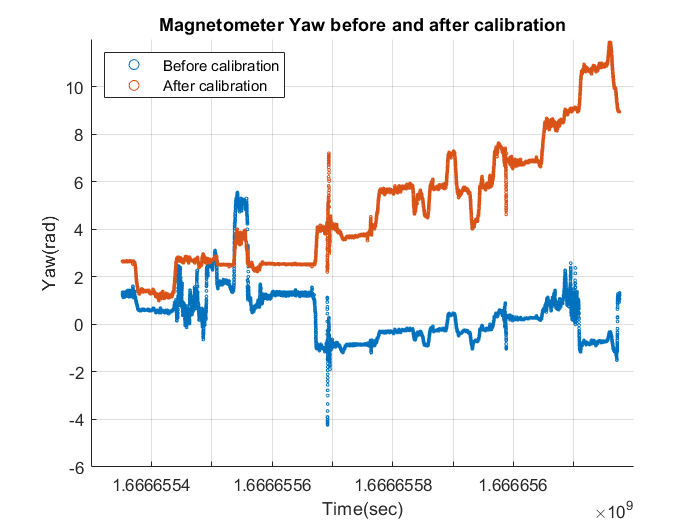

scatter(time, yaw_b,3)
hold on
scatter(time, yaw_a,3)
grid on
legend("Before calibration", "After calibration", 'Location','northwest')
xlabel("Time(sec)")
ylabel("Yaw(rad)")
title("Magnetometer Yaw before and after calibration")
hold off

Integrating gyro sensor

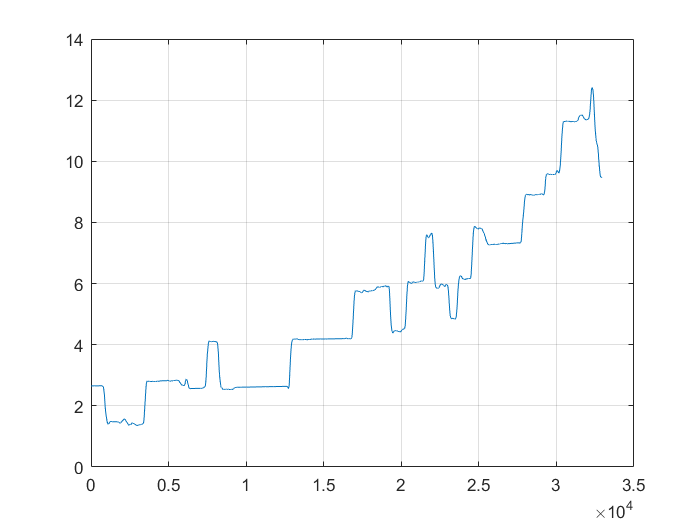

rate_yaw = [imu_d.IMUangular_velocityz];
yaw_gyro = cumtrapz(time, rate_yaw);
yaw_gyro = unwrap(yaw_gyro);
yaw_gyro = (yaw_gyro)+yaw_a(1);
plot(yaw_gyro)
grid on

Comparison between yaw values from gyrometer and calibrated magnetometer

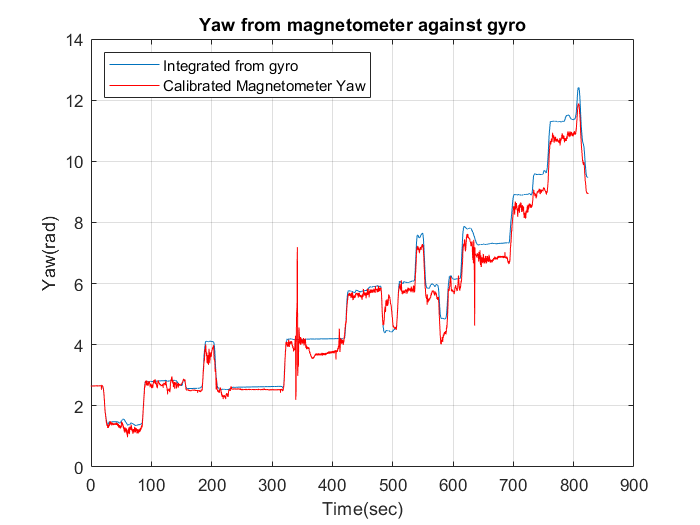

plot(time-time(1), yaw_gyro)
grid on
hold on
plot(time-time(1), yaw_a, 'r')
legend('Integrated from gyro', 'Calibrated Magnetometer Yaw',"Location","northwest")
xlabel("Time(sec)")
ylabel("Yaw(rad)")
title("Yaw from magnetometer against gyro")
hold off